**Traitement des données électromyographique (ANALYTIC)**

Contexte : analyse des données des tâches motrices de mouvements isolés sur 7 muscles de l'épaule lors de différentes actions : 

- ANALYTIC1 : flexion (élévation sagittale)

- ANALYTIC2 : abduction (élévation coronale)

- ANALYTIC3 : rotation externe (abduction 0°)

- ANALYTIC4 : rotation interne (abduction 0°)

Paramètres

clc; clear all; 

% Ajout de la bibliothèque btk 
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Toolboxs\btk'));

% Définition sujet

% SAINS
subjects = {'A1'}; %1-41

% PRE-OPERATOIRE
subjects = {'S1'}; %1-41

% POST-OPERATOIRE
subjects = {'S1'}; %1-41

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};

% Définition des analytics
analytic_labels = {... 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

Visualisation du signal brutes absolu (échelle normalisée pour tous les muscles)

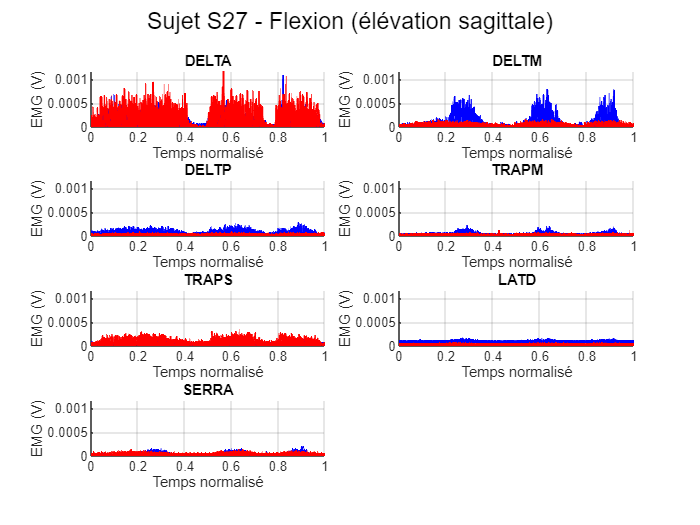

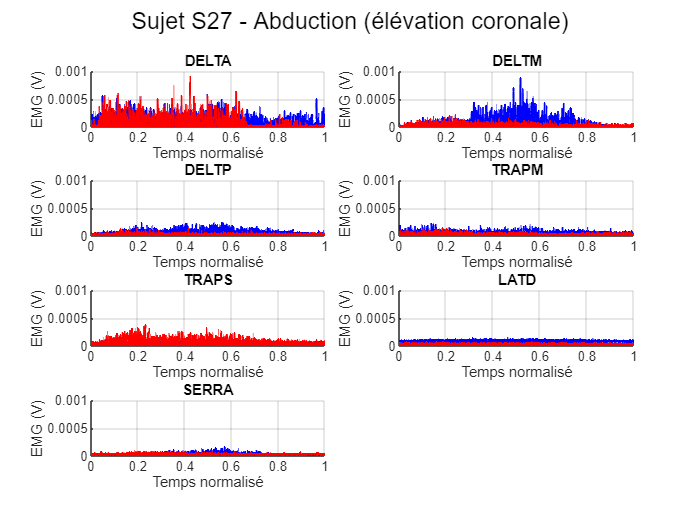

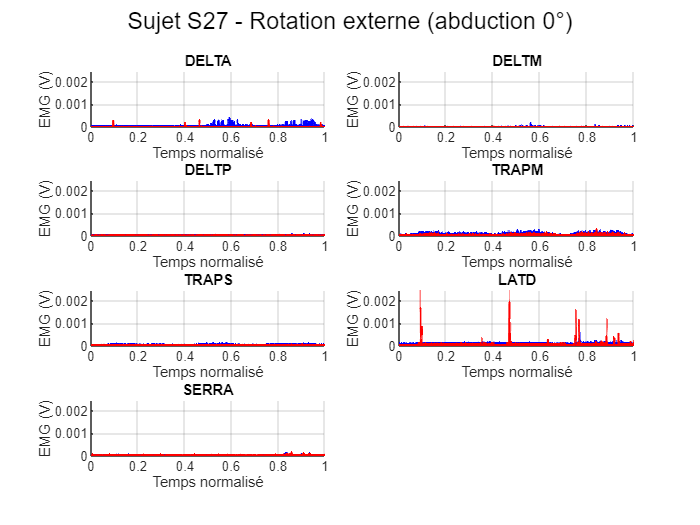

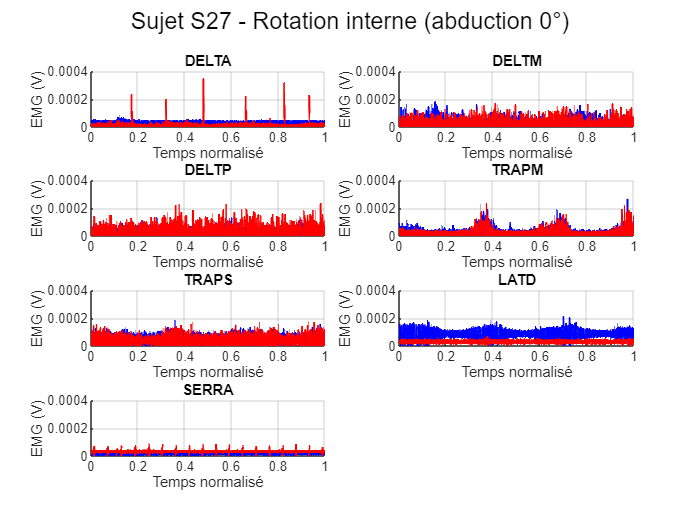

% Appel de la fonction pour obtenir les données brutes

% SAINS
plot_EMG_from_C3D_analytic(subjects, muscles_R, muscles_L, analytic_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Asymptomatic')


% PRE-OPERATOIRE
plot_EMG_from_C3D_analytic(subjects, muscles_R, muscles_L, analytic_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Pre_operation')

% POST-OPERATOIRE
plot_EMG_from_C3D_analytic(subjects, muscles_R, muscles_L, analytic_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Post_operation')